# Step 5 - Edge Detection

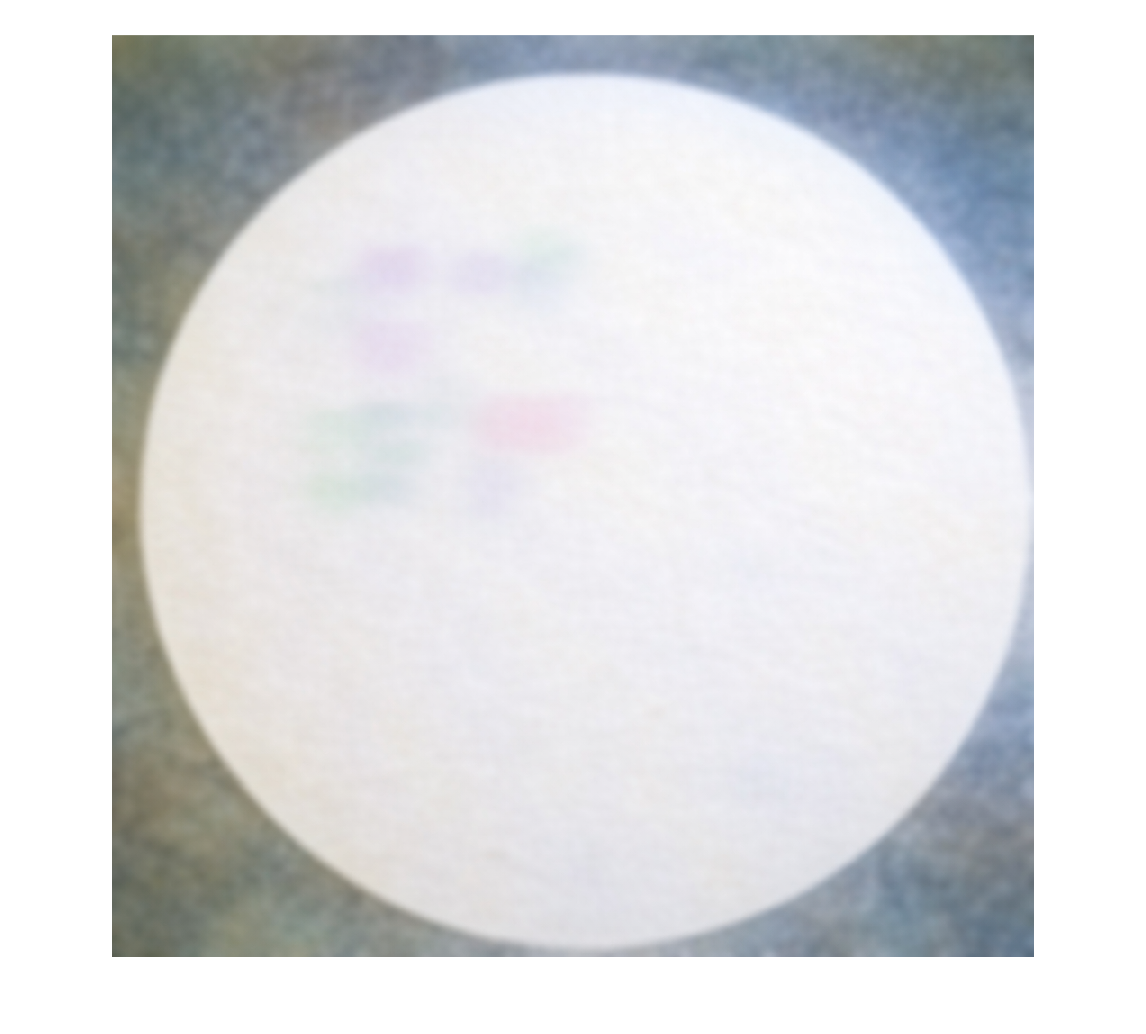

I_bilat = imread("1.png");
figure;
imshow(I_bilat);

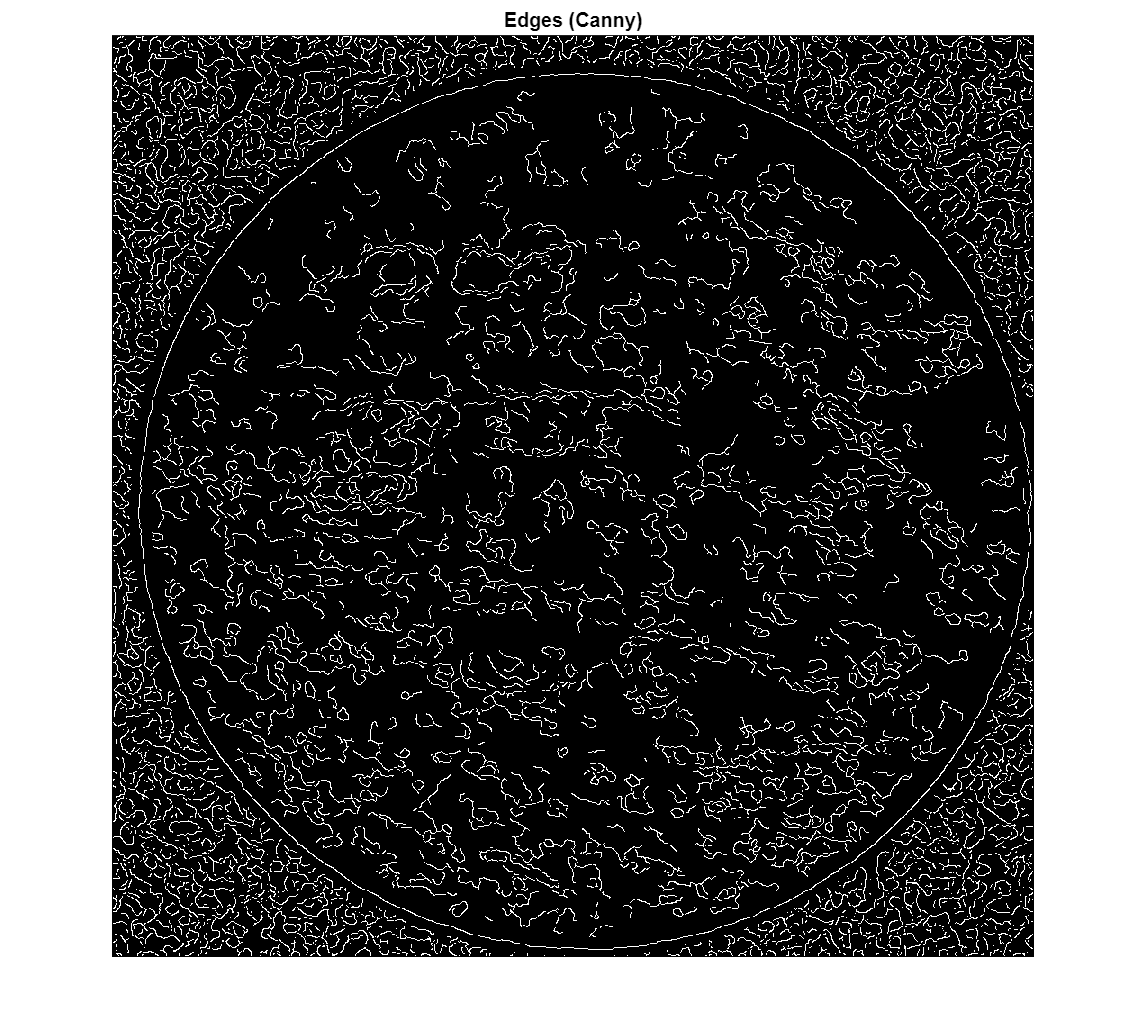


% Convert to grayscale if RGB
I_gray = rgb2gray(I_bilat);

% Edge detection (Canny)
edges_canny = edge(I_gray, 'Canny');

figure;
imshow(edges_canny);
title('Edges (Canny)');

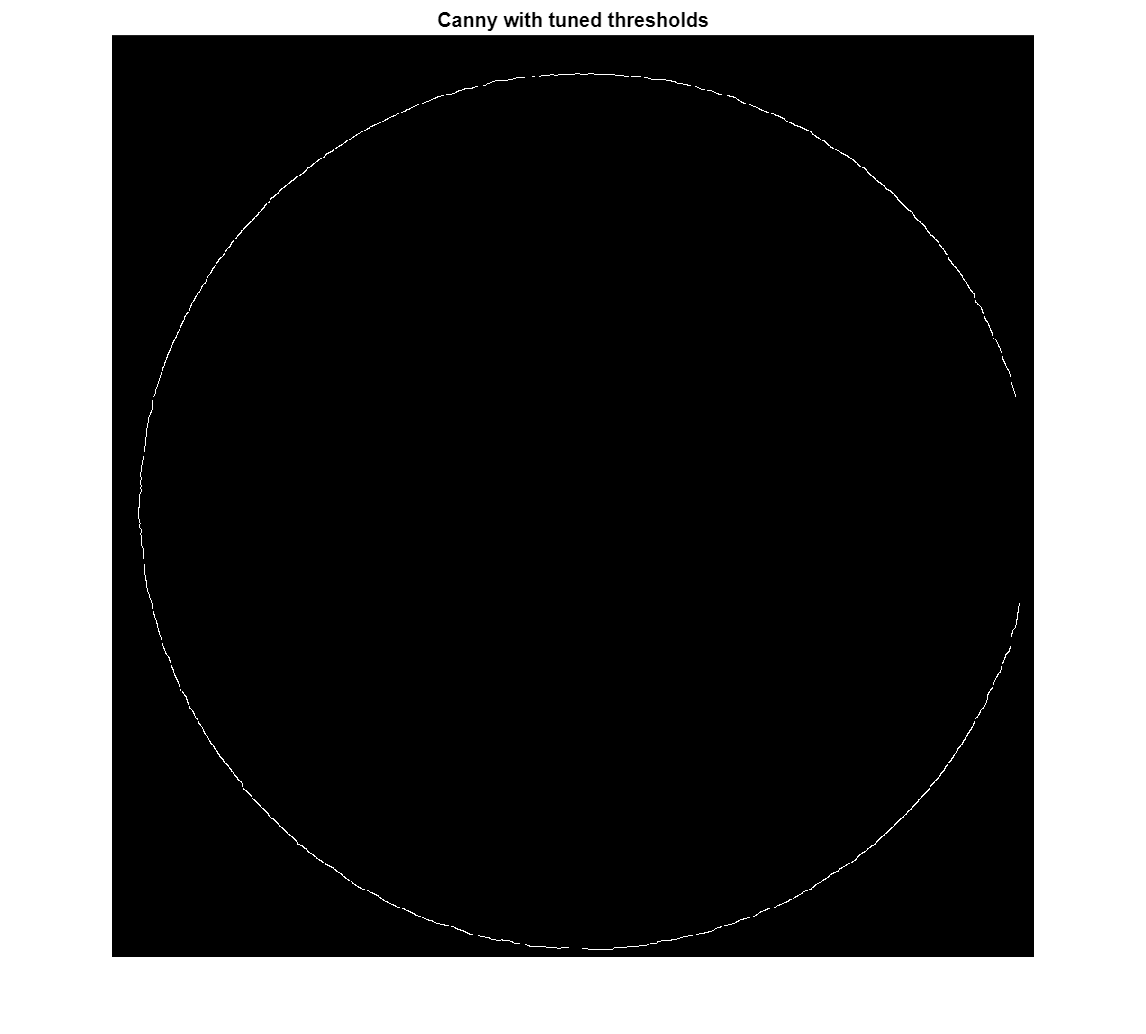

% se = strel('disk', 2);                  % structuring element
% edges_closed = imclose(edges_canny, se);
% 
% imshow(edges_closed); title('Canny + Morphological Closing');
% edges_filled = imfill(edges_closed, 'holes');
% 
% imshow(edges_filled); title('Edges after filling holes');
% edges_clean = bwareafilt(edges_filled, 1);  % keep largest blob
% 
% imshow(edges_clean); title('Final Clean Ball Edge Mask');
% I_overlay = imoverlay(I_up, edges_clean, [1 0 0]);  % red edges
% imshow(I_overlay); title('Edges Overlayed on Original');

edges_canny_tuned = edge(I_gray, 'Canny', [0.4 0.8]); % adjust thresholds
imshow(edges_canny_tuned), title('Canny with tuned thresholds');

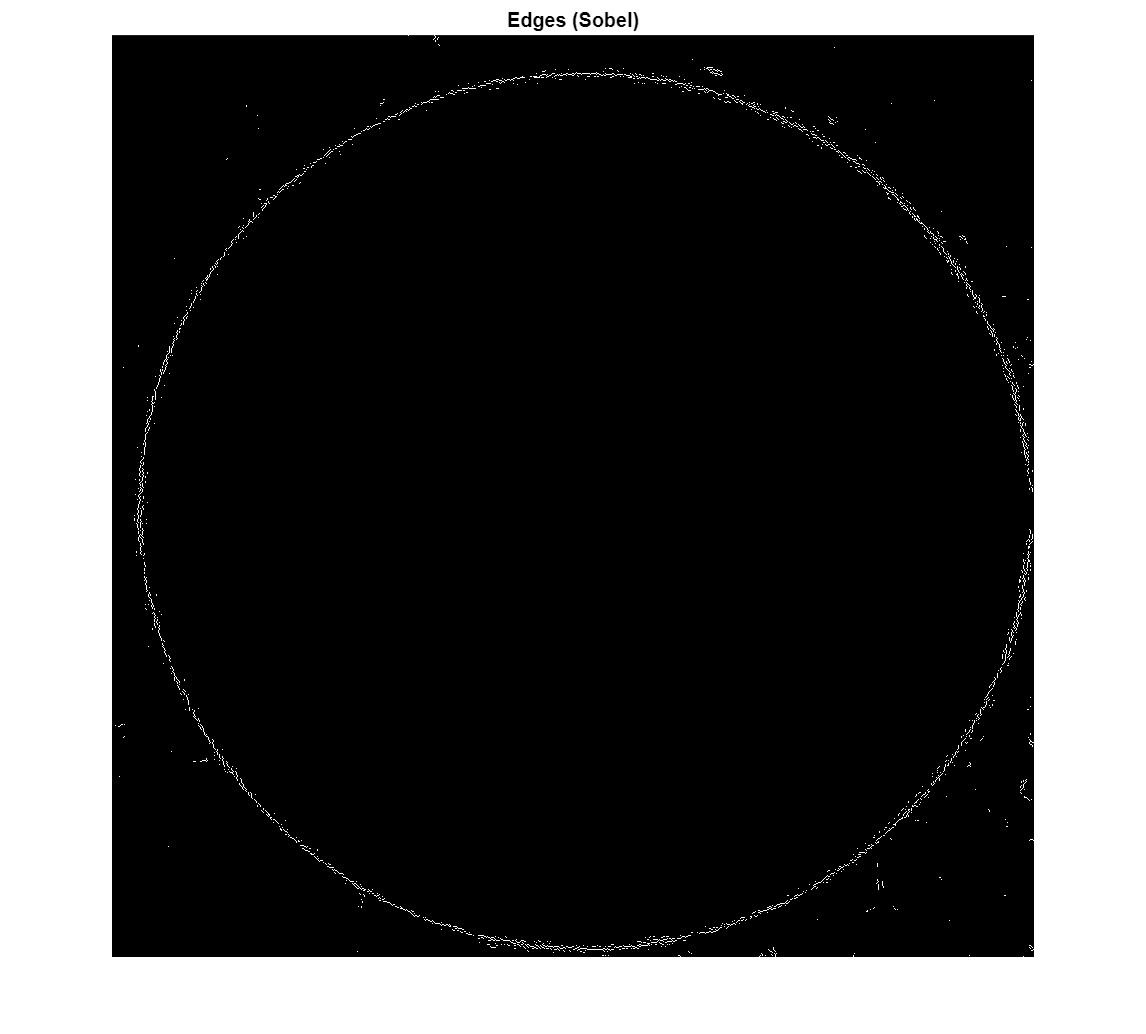

edges_sobel = edge(I_gray, 'Sobel');

figure;
imshow(edges_sobel);
title('Edges (Sobel)');

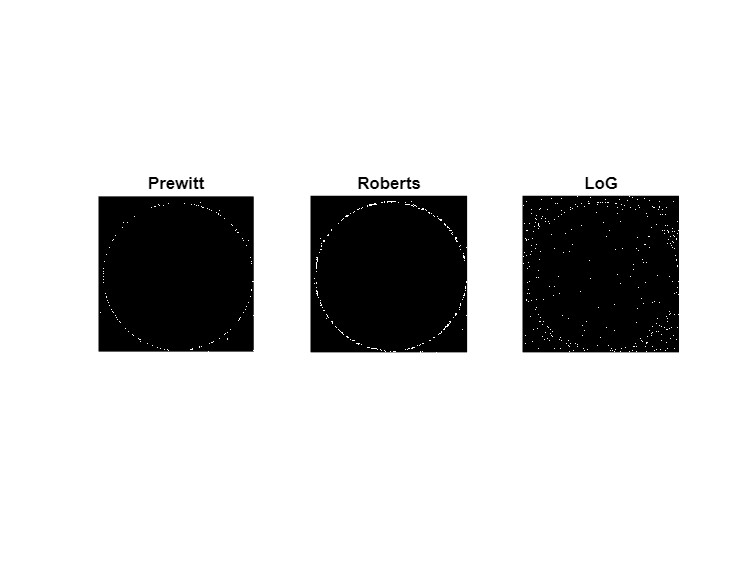

edges_prewitt = edge(I_gray, 'Prewitt');
edges_roberts = edge(I_gray, 'Roberts');
edges_log = edge(I_gray, 'log');  % Laplacian of Gaussian

figure;
subplot(1,3,1), imshow(edges_prewitt), title('Prewitt');
subplot(1,3,2), imshow(edges_roberts), title('Roberts');
subplot(1,3,3), imshow(edges_log), title('LoG');

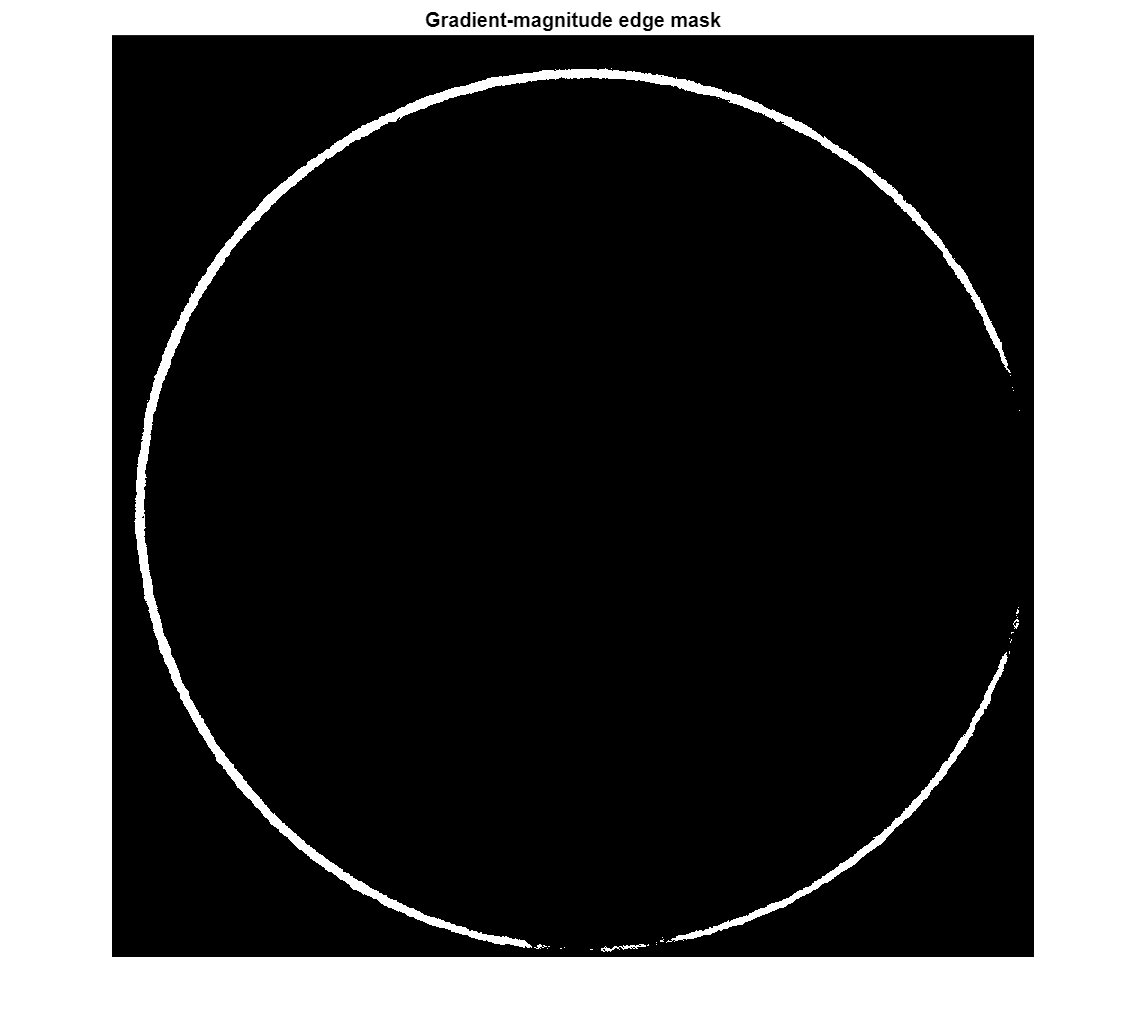

I_gray = rgb2gray(I_bilat);
[Gx, Gy] = imgradientxy(I_gray, 'sobel');
[Gmag, ~] = imgradient(Gx, Gy);

% Normalize and threshold adaptively
Gmag = mat2gray(Gmag);
T = graythresh(Gmag);  % Otsu threshold
edges_grad = Gmag > 1.5*T;  % 1.5× for cleaner outer edge

figure;imshow(edges_grad); title('Gradient-magnitude edge mask');

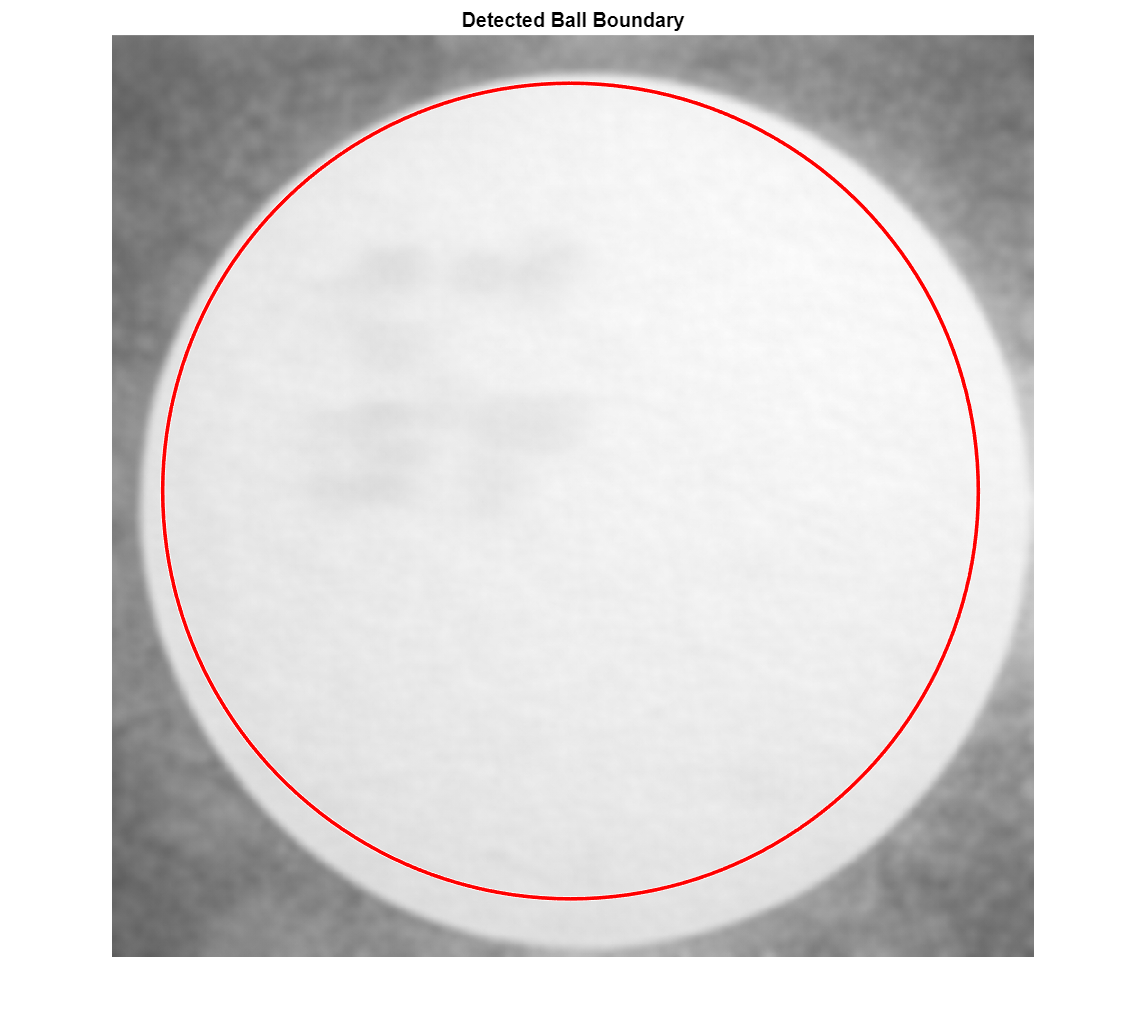


% Detect edge points from Canny or gradient mask
[rows, cols] = find(edges_canny);

% Fit a circle (least squares)
[xc, yc, R, ~] = circfit(cols, rows); % requires small helper function

% Draw on image
imshow(I_gray); hold on;
viscircles([xc, yc], R, 'Color', 'r');
title('Detected Ball Boundary');


function [xc,yc,R,a] = circfit(x,y)
    x = x(:); y = y(:);
    a = [x y ones(size(x))]\-(x.^2+y.^2);
    xc = -0.5*a(1);
    yc = -0.5*a(2);
    R = sqrt((a(1)^2+a(2)^2)/4 - a(3));
end


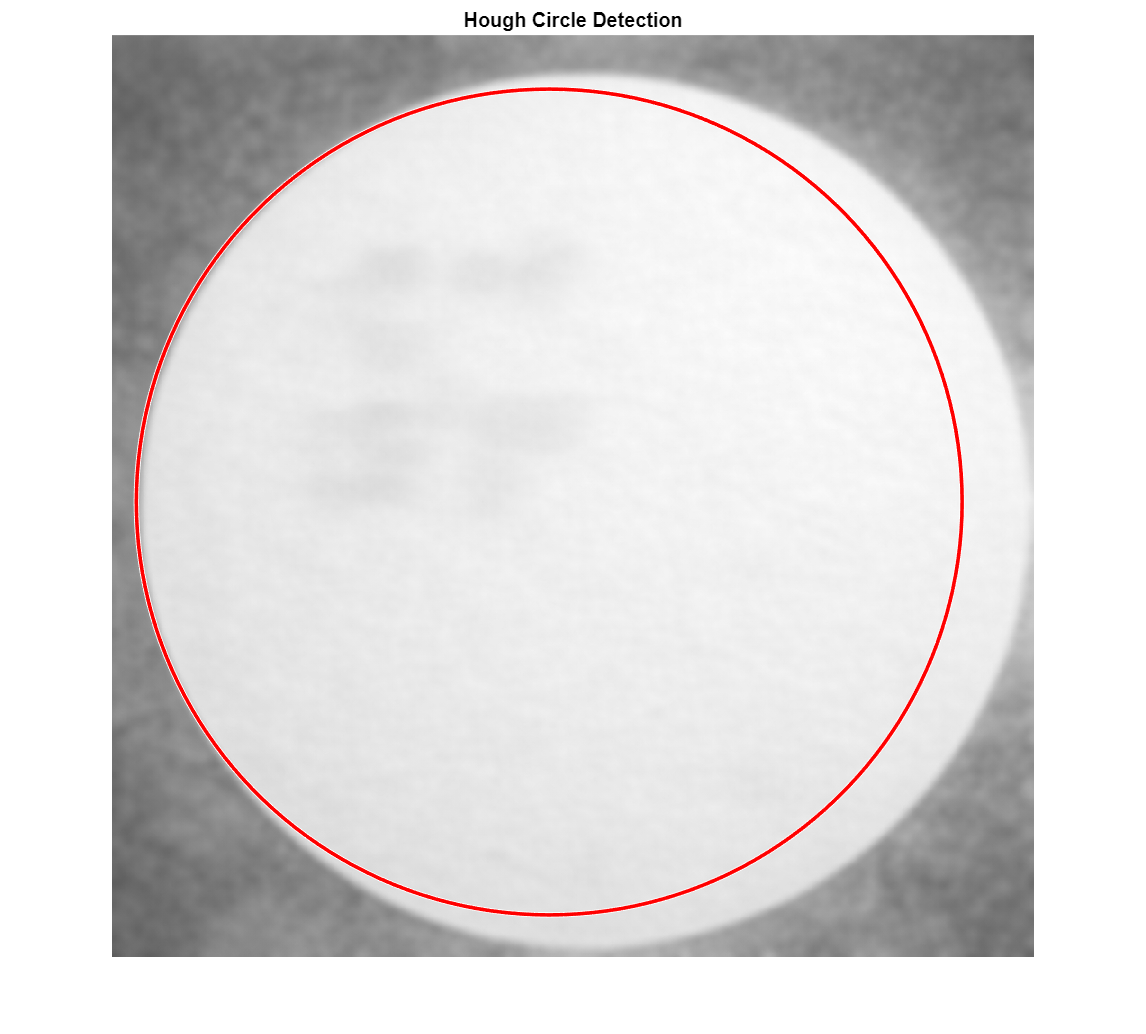

I_gray = rgb2gray(I_bilat);
[centers, radii, metric] = imfindcircles(I_gray, [160 480], ...
    'Sensitivity', 0.95, 'EdgeThreshold', 0.1);

imshow(I_gray);
viscircles(centers, radii, 'Color', 'r');
title('Hough Circle Detection');